# Elasticity PDE

Solve the elasticity pde:


$$-\nabla\cdot\sigma=\mathbf{f}\\
\mathbf{u}=\mathbf{g}$$


## Define the Problem

% parameters
lambda = 2.0;
mu = 3.0;

% solutions:
u1 = @(x, y) exp(x+y);
u2 = @(x, y) x.*y;

% f & g
f1 = @(x,y) -((lambda+3*mu)*exp(x+y)+(lambda+mu));
f2 = @(x,y) -(lambda+mu)*exp(x+y);
g1 = @(P) exp(P(1,:)+P(2,:))*atBoundary(P);
g2 = @(P) P(1,:).*P(2,:)*atBoundary(P);

Define parameters

A_nqpts = 5;
b_nqpts = 5;
v_nqpts = 3;

basis_type = 2;

## Generate Mesh

% grid size
hx = 1/8;
hy = hx;

% mesh domain
left = 0; right = 1;
bottom = 0; top = 1;

% function space
[Pb, Tb] = Gen2dTriMesh([left, right, bottom, top], hx, hy, basis_type);

nx = (right-left)/hx*basis_type+1;
ny = (top - bottom)/hy*basis_type+1;

## Define Boundary

bc = GenBoundaryNodes(nx, ny);

## Assemble Stiffness Matrices

A1 = AssembleStiff2d(Pb, Tb, A_nqpts, [1,0;1,0], @(x, y)lambda, basis_type);
A2 = A1/lambda*mu;
A3 = AssembleStiff2d(Pb, Tb, A_nqpts, [0,1;0,1], @(x, y)mu, basis_type);

A4 = AssembleStiff2d(Pb, Tb, A_nqpts, [1,0;0,1], @(x, y)lambda, basis_type);
A5 = A4'/lambda*mu; % AssembleStiff2d(Pb, Tb, A_nqpts, [0,1;1,0], @(x, y)mu, basis_type);

A6 = A5/mu*lambda;
A7 = A4/lambda*mu;

A8 = A3/mu*lambda;
A9 = A3;
A10 = A2;

## Assemble Load Vectors

b1 = AssembleLoad2d(Pb, Tb, b_nqpts, [0 0], f1, basis_type);
b2 = AssembleLoad2d(Pb, Tb, b_nqpts, [0 0], f2, basis_type);

## Build Linear System

Aup = [A1+2*A2+A3, A4+A5];
Adn = [A8+2*A9+A10, A6+A7];

## Apply Boundary Conditions

[Aup, b1, ~] = ApplyBoundaryDirchlet2d(Aup, b1, bc, Pb, g1);
[Adn, b2, ~] = ApplyBoundaryDirchlet2d(Adn, b2, bc, Pb, g2);
Adn = swap(Adn);

## Get Solution

A = [Aup;Adn];
b = [b1;b2];
x = A\b;

xl = numel(x);
x1 = x(1:xl/2);
x2 = x(xl/2+1:end);

## Plot solutions

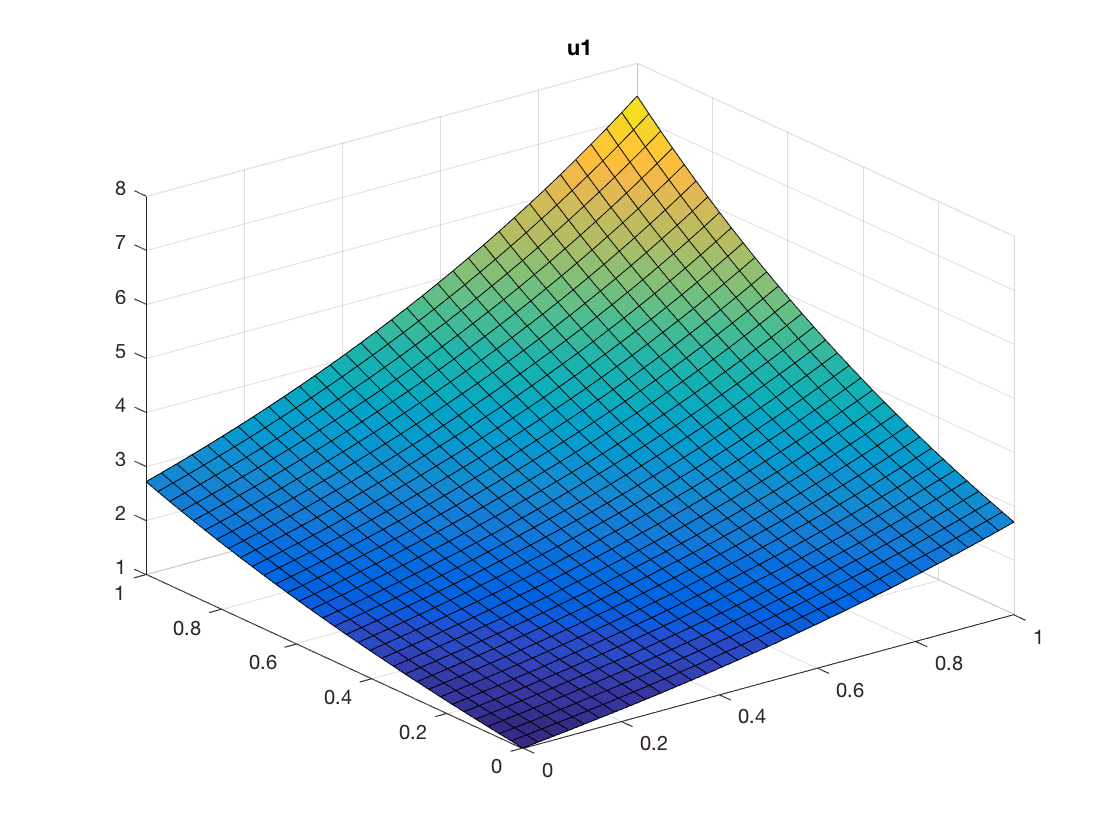

U1 = reshape(x1, ny, nx);
U2 = reshape(x2, ny, nx);
x = left:hx/basis_type:right;
y = bottom:hy/basis_type:top;
[X,Y] = meshgrid(x,y);

surf(X,Y,U1);
title('u1');

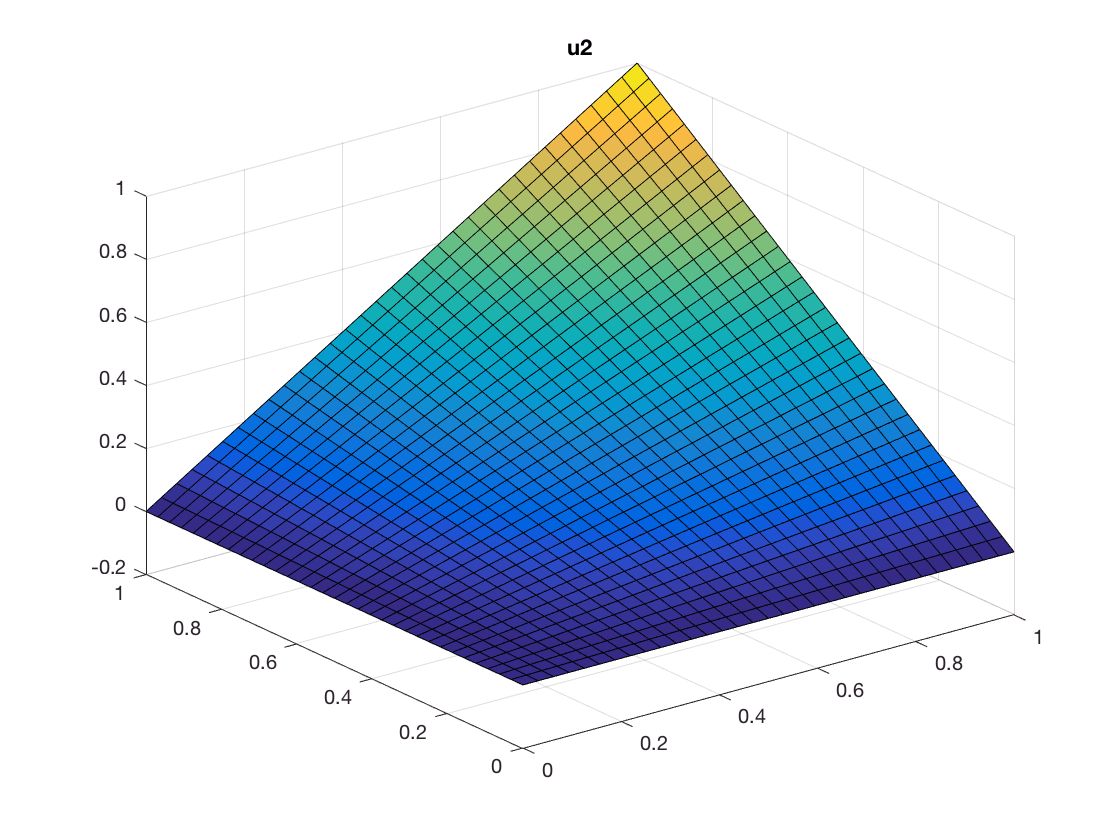

surf(X,Y,U2);
title('u2');

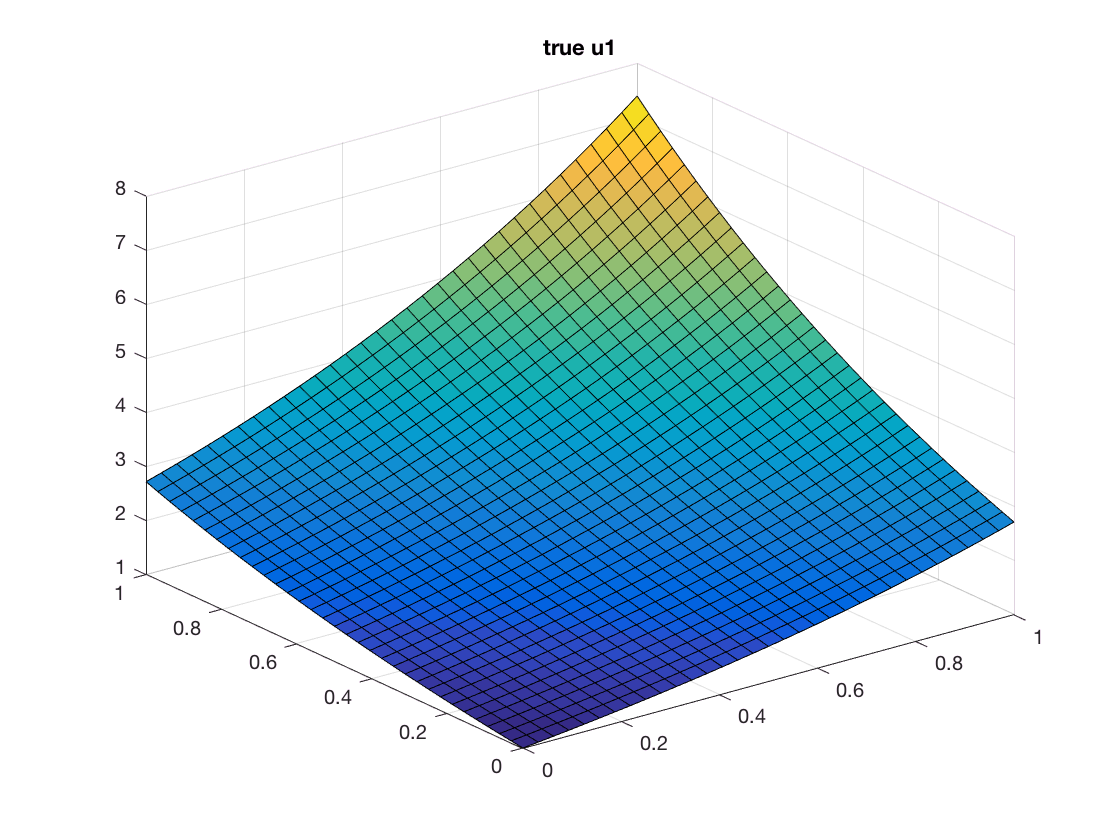

surf(X,Y,u1(X,Y));
title('true u1');

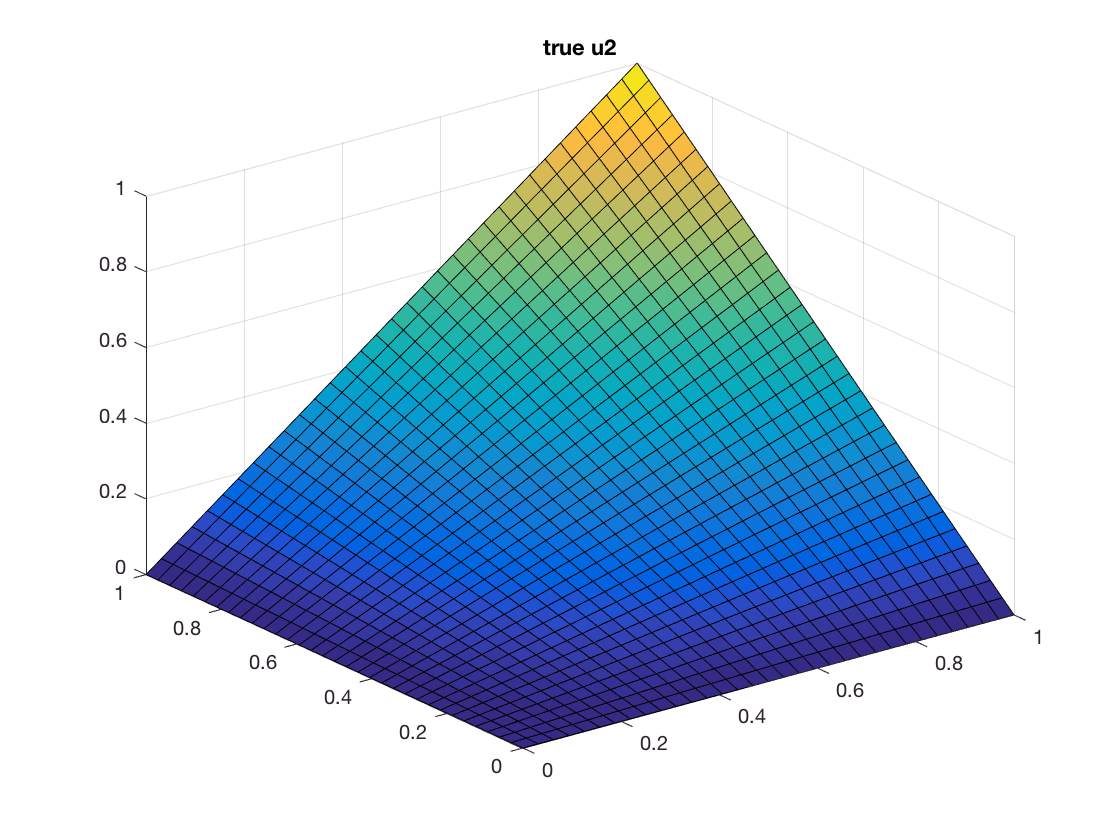

surf(X,Y,u2(X,Y));
title('true u2');

## Calculate Error Norms

err1L2 = errorNorm(x1, u1, Pb, Tb, basis_type, A_nqpts, 'L2');
err2L2 = errorNorm(x2, u2, Pb, Tb, basis_type, A_nqpts, 'L2');

err1Inf = errorNorm(x1, u1, Pb, Tb, basis_type, A_nqpts, 'inf');
err2Inf = errorNorm(x2, u2, Pb, Tb, basis_type, A_nqpts, 'inf');

err1H1 = errorNorm(x1, {u1, u1}, Pb, Tb, basis_type, A_nqpts, 'H1');
err2H1 = errorNorm(x2, {@(x,y)y, @(x,y)x}, Pb, Tb, basis_type, A_nqpts, 'H1');

fileID = fopen('error_norms.txt','a+');
fprintf(fileID, 'h = %s, inf error, L2 error, H1 error\n', strtrim(rats(hx)));
fprintf(fileID, '  u1:     %6.2g,    %6.2g,    %6.2g\n', err1Inf, err1L2, err1H1);
fprintf(fileID, '  u2:     %6.2g,    %6.2g,    %6.2g\n', err2Inf, err2L2, err2H1);
fclose(fileID);

## Helper functions:

function A = swap(A)
    n = size(A, 2);
    assert(mod(n, 2)==0);
    h = n/2;
    A = [A(:, h+1:end), A(:,1:h)];
end

function r = atBoundary(P)
    x = P(1,:);
    y = P(2,:);
    atB = ((x == 1 | x == 0) | (y == 1 | y == 0));
    assert(all(atB));
    r = 1;
end